# One Patient

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

clearvars; clc;
patients = find_patients('eeg');
patient = patients{1};
classifiers_fold_root = './classifiers/';

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ah7


info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.feedback_code = 781;

info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};

## load EEG for online data - compute Laplacian referencing and PSD

PSD_data = cell(size(patient.online_files));
for f = 1:length(patient.online_files)
    % Raw EEG
    [s, h] = sload(patient.online_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{f} = psd_extraction(s, h);
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


## common data

here we suppose the frequecies of the PSD don't change between the files

info.frequencies = PSD_data{1}.frequencies;
[PSD, EVENT, run_k] = concatenatePSD(PSD_data);

## label data

[cue_k, trial_k] = label_data(EVENT, length(PSD));

## log and sub-frequences extraction

[PSD, info.frequencies] = extract_frequencies(PSD, info.frequencies, info.selected_frequencies);
PSD = log(PSD); 

## load classifier data

load(strcat(classifiers_fold_root, patient.name, '_classifier'));

## convert PSD into dataset for the classifier

dataset = extract_features(PSD, selected_features);

# CLASSIFIER TEST

## extract test set

classes = [info.cue_BF, info.cue_BH];
bh_index = (cue_k== info.cue_BH);
bf_index = (cue_k== info.cue_BF);

test_set = dataset(bh_index | bf_index, :);
true_labels = cue_k(bh_index | bf_index);

## test the model on online data

predicted_labels = predict(model, test_set);
[accuracy, accuracy_per_class] = evaluate_classifier(true_labels, predicted_labels, classes)

accuracy = 73.4216

accuracy_per_class =    74.8002   72.5689


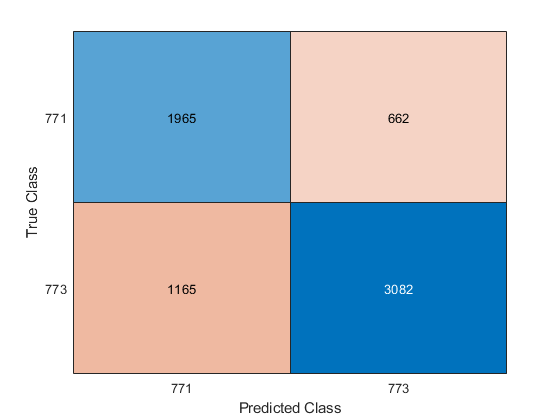

confusionchart(true_labels, predicted_labels);

# Evidence Accumulation tuning

classify and accumulate evidence over the feedback period of offline runs, we use the offline data to tune parameters that are next tested in the online data.

the evidence accumulation is based on the posterior probability of class 771 both feet

## data

% online data of the first day
tuning_index = (run_k==1);

data_tuning = dataset(tuning_index, :);
data_test = dataset(~tuning_index, :);

trial_k_tuning = trial_k(tuning_index);
trial_k_test = trial_k(~tuning_index);

true_class = EVENT.TYP(EVENT.TYP==info.cue_BF | EVENT.TYP==info.cue_BH | EVENT.TYP==info.cue_rest);
num_trials_tuning = length(nonzeros(unique(trial_k_tuning)));
true_class_tuning = true_class(1:num_trials_tuning);
true_class_test = true_class(num_trials_tuning + 1:end);

feedbk_ind = labels_for_event(EVENT, info.feedback_code, length(PSD));
feedbk_ind_tuning = feedbk_ind(tuning_index);
feedbk_ind_test = feedbk_ind(~tuning_index);


%predict on data
[~,post_prob_tuning] = predict(model, data_tuning);
[~,post_prob_test] = predict(model, data_test);

num_classes = length(classes);
% vector of start of feedback for each trial
feedbk_starts = EVENT.POS(EVENT.TYP==info.feedback_code);
feedbk_starts_tuning = feedbk_starts(1 : num_trials_tuning);
feedbk_starts_test = feedbk_starts(num_trials_tuning+1 : end);
% map the feedback starts for test to start from the first data after tuning
feedbk_starts_test = feedbk_starts_test - size(data_tuning, 1);

## Exponential smoothing

framework = @(alpha) exponential_smoothing(post_prob_tuning, num_classes, feedbk_starts_tuning, alpha);
evaluation = @(x) fitness(x(2), x(3), true_class_tuning, framework(x(1)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 3, [], [], [], [], [0 0.5 0], [1 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



exp_param.alpha = params(1);
exp_param.up_threshold = params(2);
exp_param.down_threshold = params(3);

## Dynamic smoothing

free_force = @(ampl,w) (@(x) f_free(x, ampl, w));
bmi_force = @(x) f_bmi_sin(x);

framework = @(alpha, beta, ampl, w) dynamic_smoothing(post_prob_tuning, num_classes, feedbk_starts_tuning, alpha, beta, free_force(ampl, w), bmi_force);
evaluation = @(x) fitness(x(5), x(6), true_class_tuning, framework(x(1),x(2),x(3),x(4)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 6, [], [], [], [], [0 0 0 0 0.5 0], [1 1 1 0.5 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



dyn_param.alpha = params(1);
dyn_param.beta = params(2);
dyn_param.amp = params(3);
dyn_param.w = params(4);
dyn_param.up_threshold = params(5);
dyn_param.down_threshold = params(6);

## moving average

framework = @(alpha) mov_avg_smoothing(post_prob_tuning, num_classes, feedbk_starts_tuning, alpha);
evaluation = @(x) fitness(x(2), x(3), true_class_tuning, framework(x(1)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 3, [], [], [], [], [0 0.5 0], [1 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



mov_param.alpha = params(1);
mov_param.up_threshold = params(2);
mov_param.down_threshold = params(3);

# EVIDENCE ACCUMULATION PERFORMANCE ON TRAIN

## classify data

accumulator_ex = exponential_smoothing(post_prob_tuning, num_classes, feedbk_starts_tuning, exp_param.alpha);
accumulator_dyn = dynamic_smoothing(post_prob_tuning, num_classes, feedbk_starts_tuning, dyn_param.alpha, dyn_param.beta, free_force(dyn_param.amp, dyn_param.w), bmi_force);
accumulator_mov = mov_avg_smoothing(post_prob_tuning, num_classes, feedbk_starts_tuning, mov_param.alpha);

## trial accuracy

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(exp_param.up_threshold, exp_param.down_threshold, true_class_tuning, accumulator_ex, feedbk_ind_tuning, trial_k_tuning)

perf_active_ex = 80

perf_resting_ex = 50

perf_active_rej_ex = 100

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(dyn_param.up_threshold, dyn_param.down_threshold, true_class_tuning, accumulator_dyn, feedbk_ind_tuning, trial_k_tuning)

perf_active_dyn = 15

perf_resting_dyn = 100

perf_active_rej_dyn = 100

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(mov_param.up_threshold, mov_param.down_threshold, true_class_tuning, accumulator_mov, feedbk_ind_tuning, trial_k_tuning)

perf_active_mov = 10

perf_resting_mov = 90

perf_active_rej_mov = 100

# EVIDENCE ACCUMULATION PERFORMANCE ON TEST

## classify data

accumulator_ex = exponential_smoothing(post_prob_test, num_classes, feedbk_starts_test, exp_param.alpha);
accumulator_dyn = dynamic_smoothing(post_prob_test, num_classes, feedbk_starts_test, dyn_param.alpha, dyn_param.beta, free_force(dyn_param.amp, dyn_param.w), bmi_force);
accumulator_mov = mov_avg_smoothing(post_prob_test, num_classes, feedbk_starts_test, mov_param.alpha);

## trial accuracy

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(exp_param.up_threshold, exp_param.down_threshold, true_class_test, accumulator_ex, feedbk_ind_test, trial_k_test)

perf_active_ex = 80

perf_resting_ex = 26.6667

perf_active_rej_ex = 94.1176

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(dyn_param.up_threshold, dyn_param.down_threshold, true_class_test, accumulator_dyn, feedbk_ind_test, trial_k_test)

perf_active_dyn = 5

perf_resting_dyn = 80

perf_active_rej_dyn = 100


[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(mov_param.up_threshold, mov_param.down_threshold, true_class_test, accumulator_mov, feedbk_ind_test, trial_k_test)

perf_active_mov = 3.3333

perf_resting_mov = 93.3333

perf_active_rej_mov = 66.6667

function [fit] = fitness(up_threshold, down_threshold,true_class,framework,feedbk_ind,trial_k)
      [c{1:3}]= evaluate_accumulation(up_threshold, down_threshold, true_class, framework, feedbk_ind, trial_k) ;
      fit = -sum([c{:}]);
end